clear;
% fileList = dir("C:\Users\piyorin\dev\AnalyzeHoof\new3dData\*.mat")
fileList= dir("new3dData/*.mat");

length(fileList)

ans = 45

numArrays = length(fileList); % ファイルの数
data = cell(numArrays,1); % 配列事前確保
for n = 1:length(fileList)
    chr = fileList(n).name;
    data{n} = chr;
    d(n, 1) = string(chr);
end

% 
% file = uigetfile('*.mat');

file = d(21);
m = load(file);
ptCloud = m.nPoint;

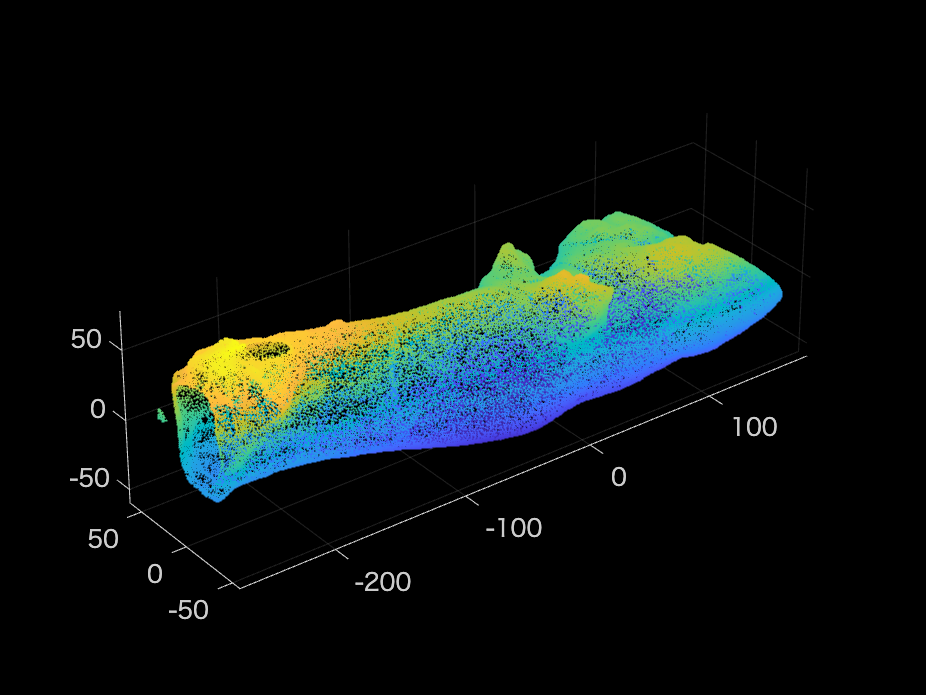

figure;
pcshow(ptCloud, AxesVisibility="on");

t = 1;
axIdx = 1;
[PosData, PointSet] = sliceModel(ptCloud, t, axIdx);

DataSize = length(PosData);
FitCircleRho = zeros(DataSize, 3);

center = mean(PosData);

index = PosData>= center;
plusSectionPos = PosData(index);
plusSectionPt = PointSet(index);


for i = 1:DataSize
    pos = PosData(i);
    point = PointSet(i);
    pt = point.Location;
    yli = point.YLimits;
    zli = point.ZLimits;
    proJ = pt(:, [2 3]);
    ymax = min(proJ(:,1));

    [thetaSorted, rhoSorted] = sortPointOnPolar(proJ);
    [x, y] = pol2cart(thetaSorted, rhoSorted);
    sortSet = [x y];
    % 近似円半径
    [cx, cy, cr] = CircleFitting(x, y);
    theta = linspace(0,2*pi,100);
    X = cr*cos(theta)+cx;
    Y = cr*sin(theta)+cy;
    FitCircleRho(i, 1) = pos;

    FitCircleRho(i,3) = cr;

%     plot(X, Y, '-m');
%     hold off;

end
sp = ptCloud.Location;
spx_max = max(sp(:,1));
idx_rho = FitCircleRho(:,1) >= center & spx_max - 10 > FitCircleRho(:,1);

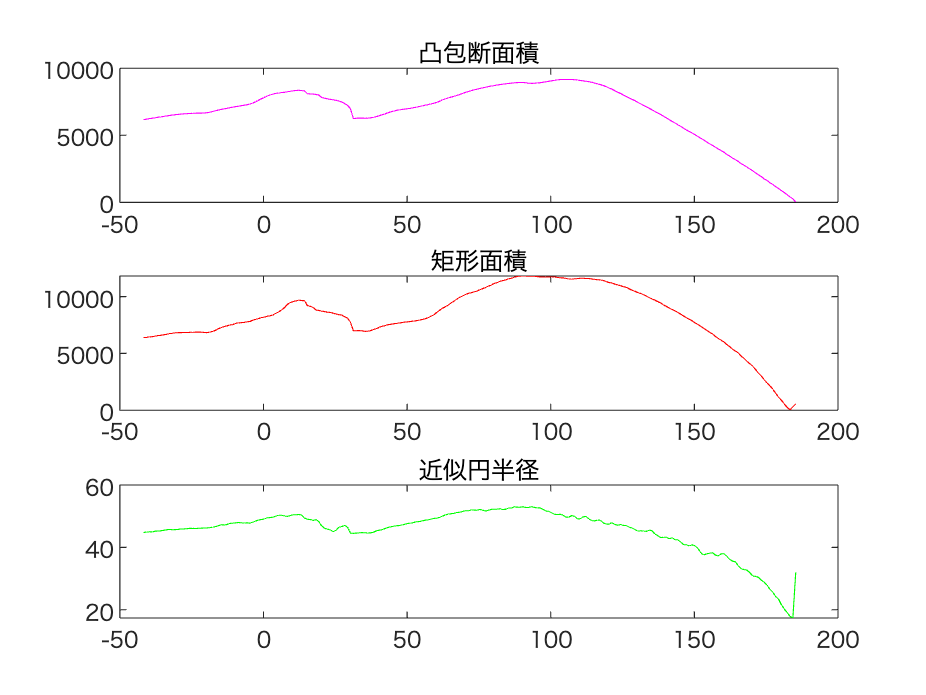

fitPos = FitCircleRho(:,1);
fitCirRho = FitCircleRho(:,3);


plfitPos = fitPos(idx_rho);
plfitCirRho = fitCirRho(idx_rho);

num = length(fitPos);
zer = zeros(num, 1);
figure("Name", 'subplot')


% plot(fitPos, fitCirRho, 'g');
plot(plfitPos, plfitCirRho, 'g');
title("近似円半径")

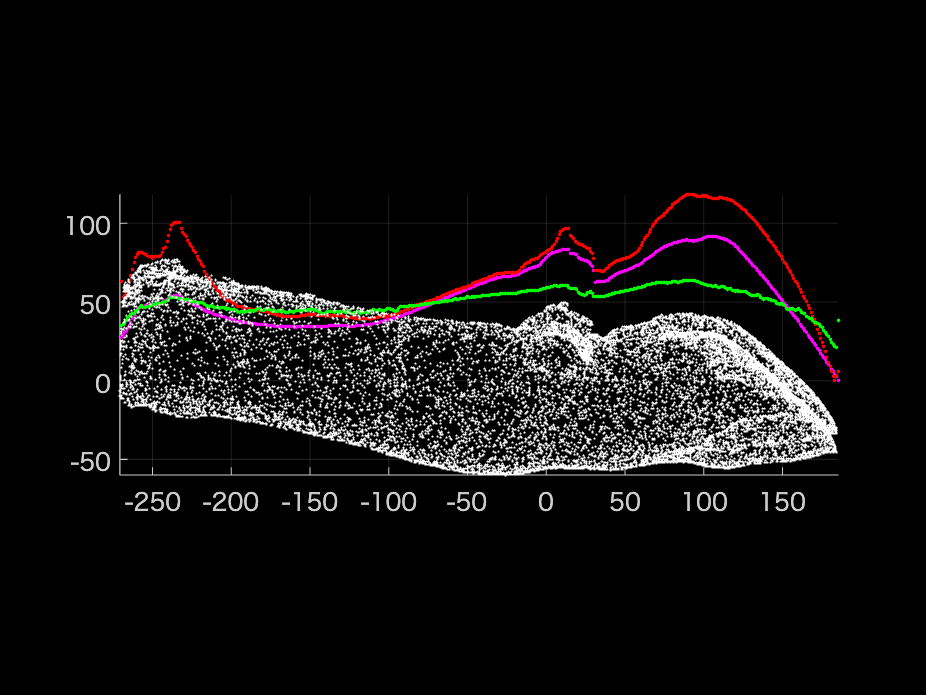


viewrho = [FitCircleRho(:,1) FitCircleRho(:,2) FitCircleRho(:,3)*1.2];

markSize = 24;
figure("Name","All-Data_PLOT")
pcshow(viewav, 'm', "MarkerSize", markSize);
hold on;
pcshow(viewrec, 'r', "MarkerSize", markSize);
pcshow(viewrho, 'g',"MarkerSize", markSize);

xli = ptCloud.XLimits;
x_range = abs(xli(2)-xli(1));

gridStep = 0.1;
% ptCloudA = pcdownsample(ptCloud,'gridAverage',gridStep);
ptCloudA = pcdownsample(ptCloud, "random", 0.2, PreserveStructure=true);
sp = ptCloudA.Location;


pcshow(sp,'w', "AxesVisibility", "on", "MarkerSize", 4, "Projection", "orthographic")
% pcshow(sp_n);
view([0 0]);
hold off

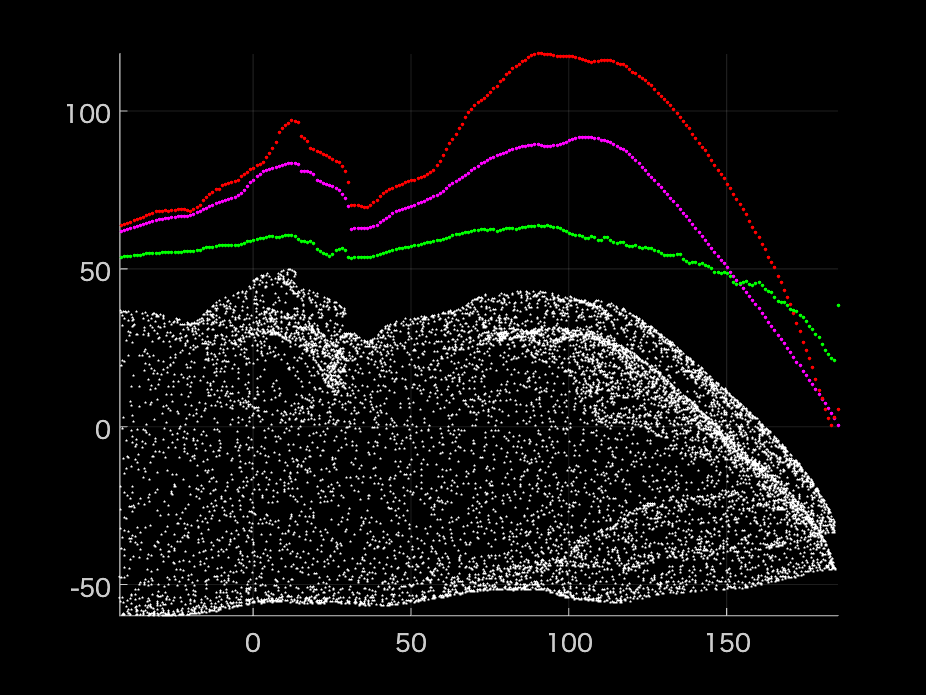

markSize = 24;
figure("Name","Plus-Data_PLOT")
pcshow(viewrho(viewrho(:,1)>=center,:), 'g',"MarkerSize", markSize);
hold on;
\

sp_c = sp(sp(:,1) >= center,:);

pcshow(sp_c,'w', "AxesVisibility", "on", "MarkerSize", 4, "Projection", "orthographic")
view([0 0]);
hold off;

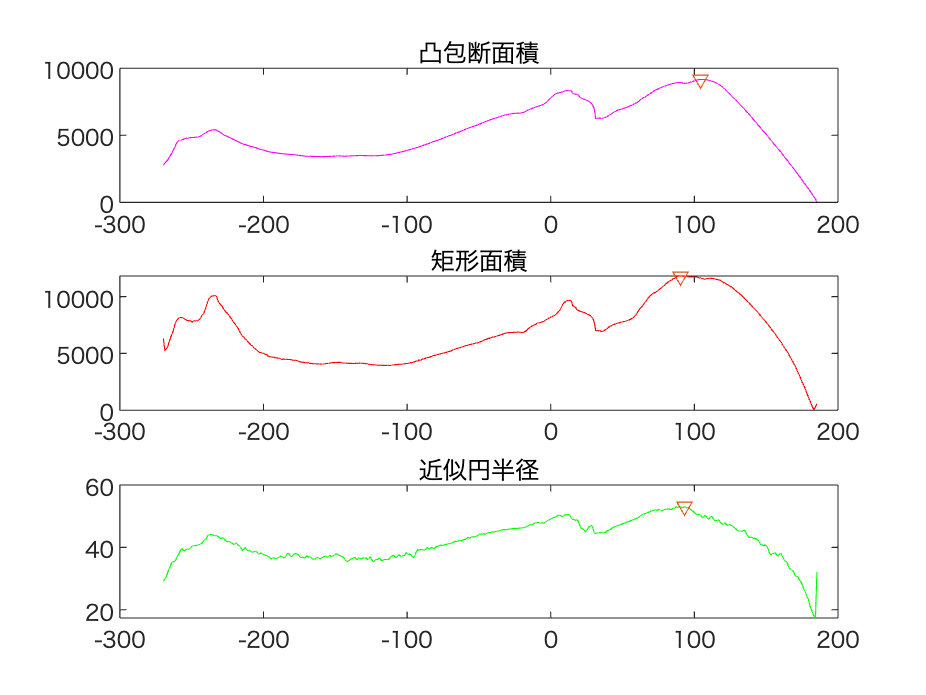


[rhMax, rh_idx] = max(FitCircleRho(:,3));

plot(fitPos, fitCirRho,'g',fitPos(rh_idx),fitCirRho(rh_idx), 'v');
title("近似円半径")

n = 3;
Wn = 0.2;

[av_y, a_v1, a_v2] = filterAnddiff(plfitCirRho, n, Wn);

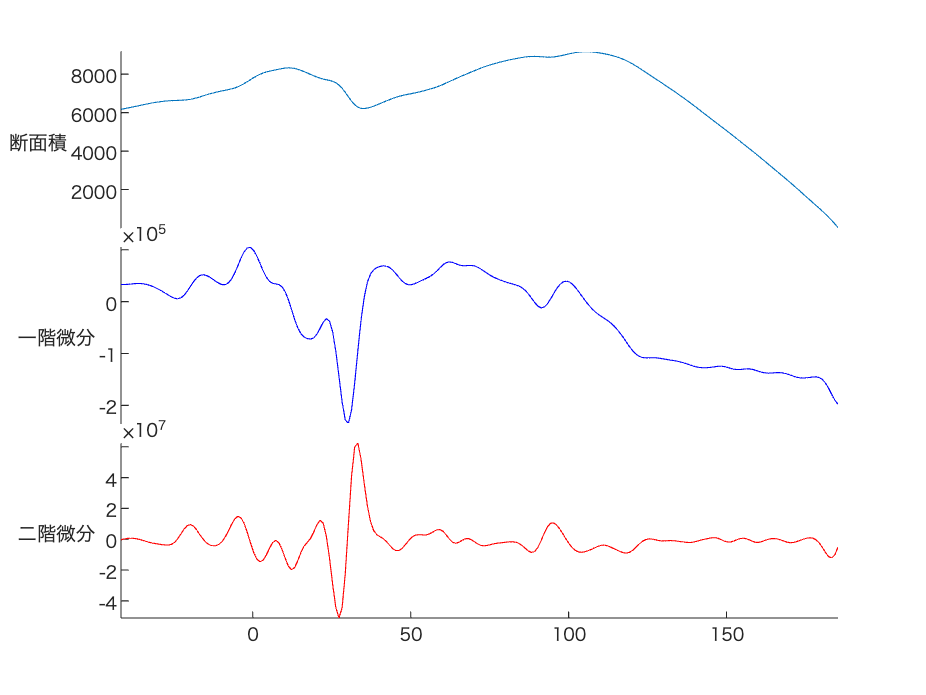

figure;
newLabels = ["断面積", "一階微分", "二階微分"];
s = stackedplot(plfitPos, [av_y, a_v1, a_v2], 'DisplayLabels',newLabels, 'Color','r');
s.LineProperties(1).Color = '#0072BD';
s.LineProperties(2).Color = 'b';
s.LineProperties(3).Color = 'r';

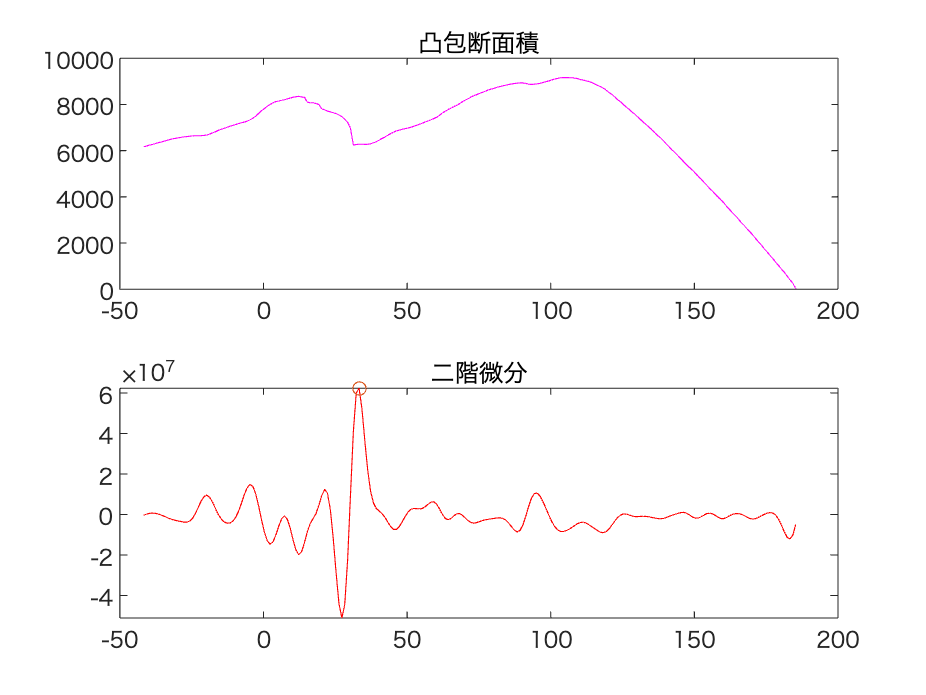

TF = islocalmin(a_v1, 'MaxNumExtrema',1 );
TF2 = islocalmax(a_v2, 'MaxNumExtrema',1);

figure("Name", 'subplot')
subplot(2,1,1)
% plot(avPos, avarea, 'm');
plot(plfitPos, plfitCirRho, 'm');
title("凸包断面積")

subplot(2,1,2)
% plot(recPos, recArea, 'r');
plot(plavPos, a_v2, 'r', plfitPos(TF2), a_v2(TF2), 'o');
title("二階微分")


sec2At = plfitPos(TF2)

sec2At =   33.281488847161199


idx_sec2 = fitPos < sec2At & sec2At-70 < fitPos;

sec2avPos = fitPos(idx_sec2);
sec2avArea = fitCirRho(idx_sec2);

[s2av_y, s2a_v1, s2a_v2] = filterAnddiff(sec2avArea, n, Wn);
s2_TF2 = islocalmax(s2a_v2, 'MaxNumExtrema',1);
[max_s2y, I_sec2] = max(s2av_y)

max_s2y =      8.325116586356917e+03


I_sec2 =     48


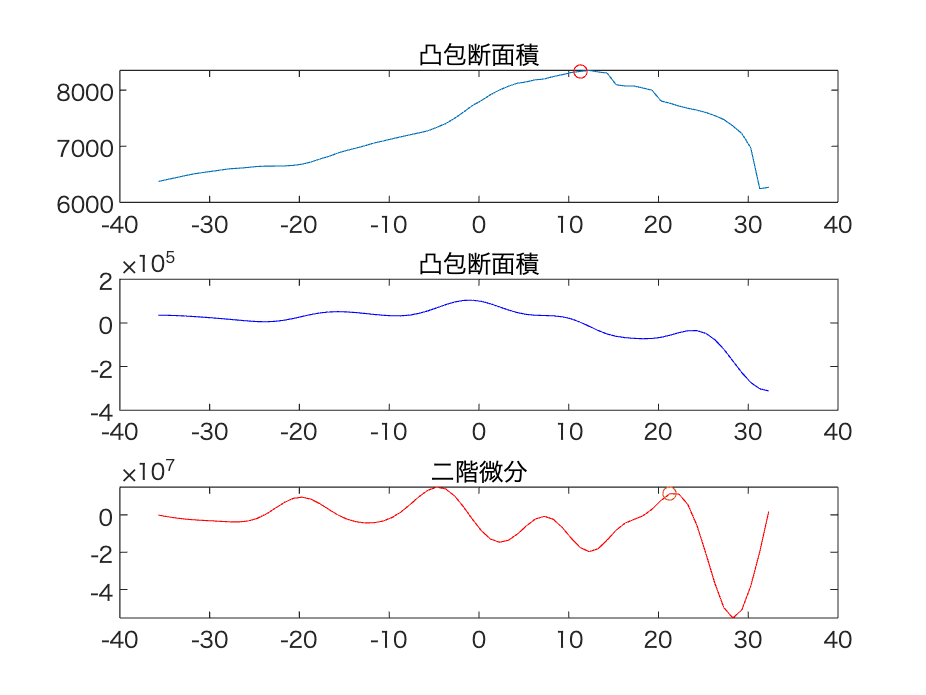


figure("Name", 'subplot')
subplot(3,1,1)
plot(sec2avPos, sec2avArea, sec2avPos(I_sec2), sec2avArea(I_sec2), 'or');
title("凸包断面積")

subplot(3,1,2)
plot(sec2avPos, s2a_v1, 'b');
title("凸包断面積")
subplot(3,1,3)
plot(sec2avPos, s2a_v2, 'r', sec2avPos(s2_TF2), s2a_v2(s2_TF2), 'o');
title("二階微分")

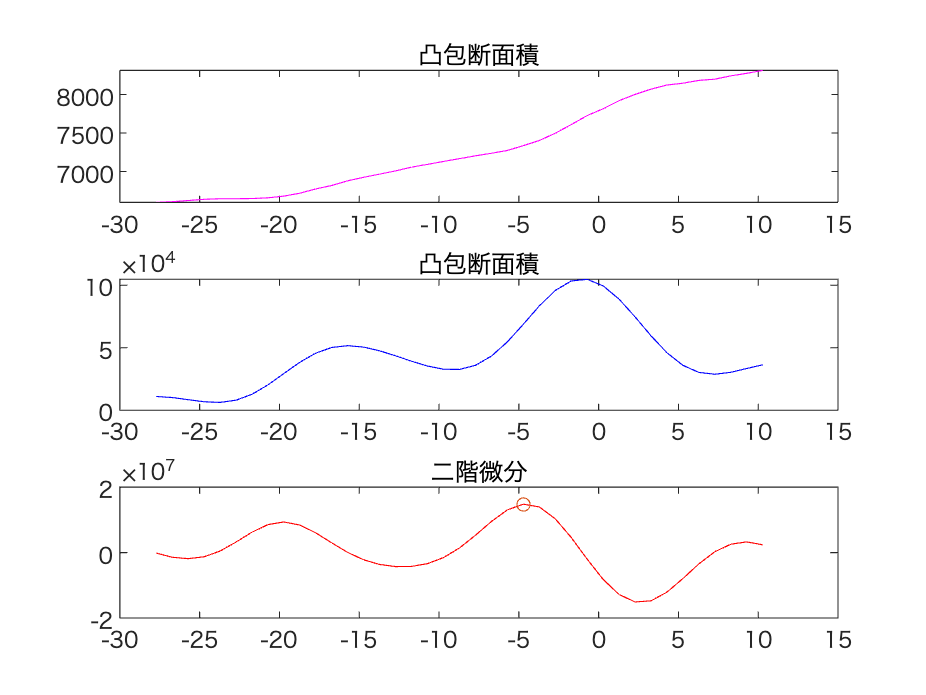

sec3At = sec2avPos(I_sec2);
idx_sec3 = fitPos < sec3At & sec3At-40 < fitPos;

sec3avPos = fitPos(idx_sec3);
sec3avArea = fitCirRho(idx_sec3);
[s3av_y, s3a_v1, s3a_v2]= filterAnddiff(sec3avArea, n, Wn);
s3_TF = islocalmax(s3a_v1, 'MaxNumExtrema',1);
s3_TF2 = islocalmax(s3a_v2, 'MaxNumExtrema',1);
figure("Name", 'subplot')
subplot(3,1,1)
plot(sec3avPos, sec3avArea, 'm');
title("凸包断面積")

subplot(3,1,2)
plot(sec3avPos, s3a_v1, 'b');
title("凸包断面積")

subplot(3,1,3)
plot(sec3avPos, s3a_v2, 'r', sec3avPos(s3_TF2), s3a_v2(s3_TF2), 'o');
title("二階微分")


CircumCenter = sec3avPos(s3_TF2);

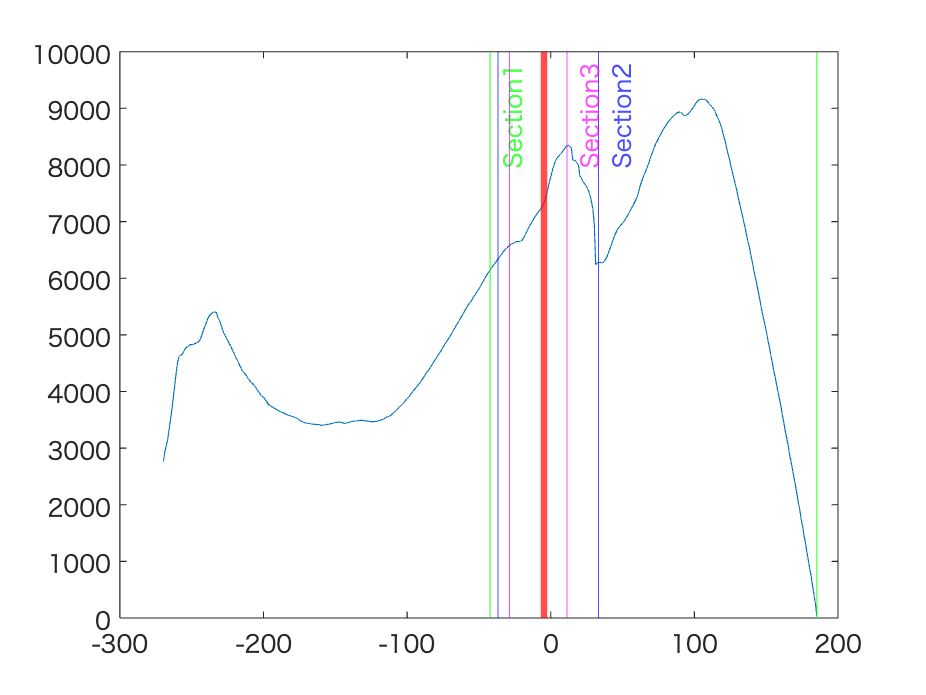

sec2At;
sec3At;
sec1At = center;
sec2_xline = sec2At;
sec3_xline = sec3At;
sec1_max = max(fitPos);

x_line = repmat(CircumCenter,200, 1);
z_line = linspace(-100, 125, 200)';
y_line = zeros(200, 1);
y_line2 = zeros(length(fitPos), 1);
pc_line = [x_line y_line z_line];
pc_conv = [avPos y_line2 fitCirRho/100];
sfig1 = figure("Name", "Show_Section");
plot(fitPos, fitCirRho);
xline(sec1At, '-g', {'Section1'});
xline(sec1_max, '-g')
xline(sec2_xline, '-b',{'Section2'});
xline(sec2_xline-70,'-b');
xline(sec3_xline, '-m',{'Section3'});
xline(sec3_xline-40, '-m');
xline(CircumCenter, '-r', 'LineWidth',3);

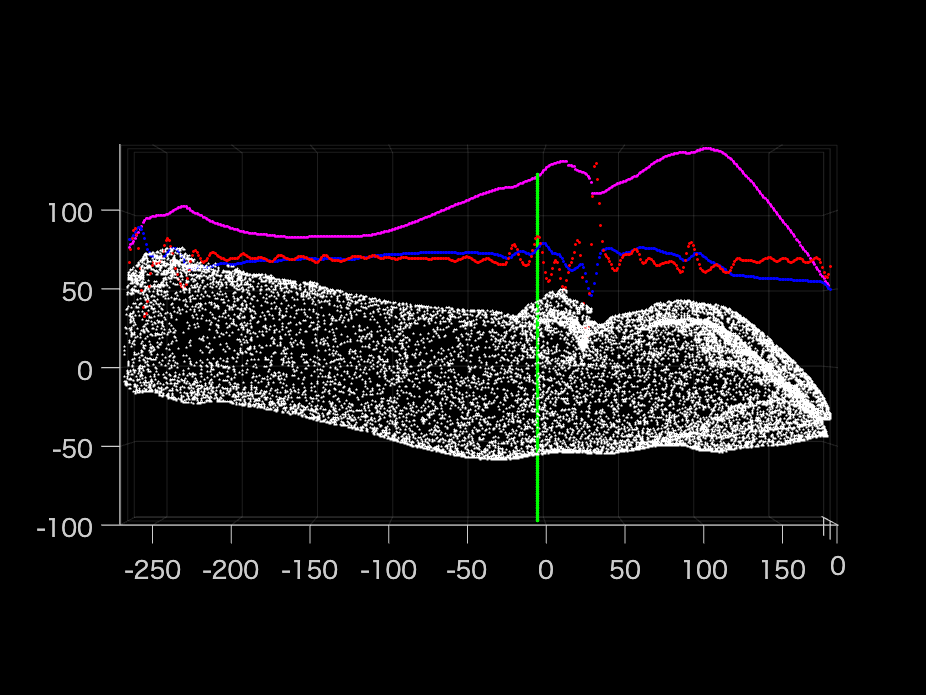



viewav = [FitCircleRho(:,1)  FitCircleRho(:,2) FitCircleRho(:,3)*1.2+50];
[Y, aV1, aV2] = filterAnddiff(FitCircleRho(:,3)/100, n, Wn);
pt = ptCloudA.Location;

diff1_pc = [FitCircleRho(:,1) FitCircleRho(:,2), (aV1/100)+70];
diff2_pc = [FitCircleRho(:,1) FitCircleRho(:,2), (aV2/10000)+70];
sfig2 = figure("Name","GETFIG");
pcshow(viewav, 'm', 'MarkerSize', 15);
hold on;
pcshow(pc_line, 'g', 'MarkerSize', 25);
pcshow(diff1_pc, 'b','MarkerSize', 20)
pcshow(diff2_pc, 'r','MarkerSize', 20)
pcshow(pt, 'w', 'AxesVisibility', 'on');
view([0 0])
hold off

sampleWidth = 5;
getCase1 = [CircumCenter, CircumCenter-sampleWidth];
getCase2 = [CircumCenter-sampleWidth, CircumCenter-sampleWidth*2];

idx1 = PosData >= getCase1(2) & getCase1(1) >= PosData;
idx2 = PosData >= getCase2(2) & getCase2(1) >= PosData;
getPoint1 = PointSet(idx1);
getPoint2 = PointSet(idx2);
getPoint1(1)

ans =   pointCloud のプロパティ:

     Location: [335×3 double]
        Count: 335
      XLimits: [-10.717023061398915 -8.731415109344775]
      YLimits: [-44.504199881794982 44.650195220300944]
      ZLimits: [-58.098690133083792 41.210811974134941]
        Color: []
       Normal: []
    Intensity: []


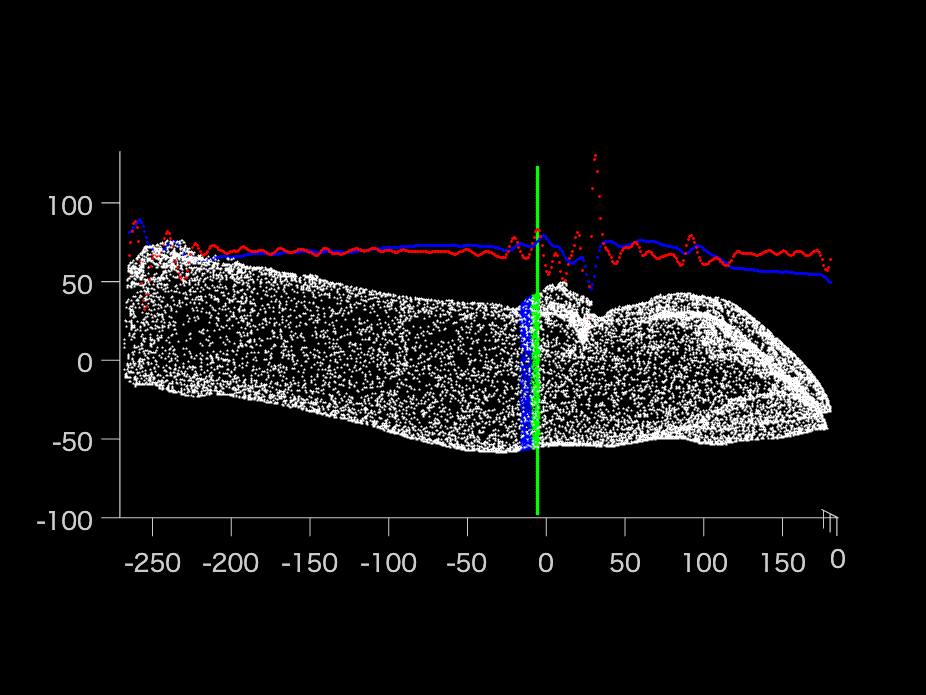


sfig3 = figure('Name', 'marking');
hold on;
pcshow(ptCloudA, 'AxesVisibility', 'on');
pcshow(pc_line, 'r')
leng1 = zeros(length(getPoint1), 1);
leng2 =  zeros(length(getPoint2), 1);
% at1 = onews(length())
atCir1 = [];
atCir2 = [];
for i = 1:length(getPoint1)
    gp = getPoint1(i).Location;
    gp_c= [gp(:,2) gp(:,3)];
    [thetaSorted, rhoSorted] = sortPointOnPolar(gp_c);
    [gp_x, gp_y] = pol2cart(thetaSorted, rhoSorted);
    gp_cross = [gp_x gp_y];
    try
        k = convhull(gp_cross);
    catch
        continue;
    end
    gpk = [gp_cross(k, 1), gp_cross(k,2)];
%     figure(i);
%     plot(gpk(:,1), gpk(:,2), '-or');
    len = calculateLengthForPoint(gpk);
    leng1(i) = len; 
    pcshow(gp, 'g', AxesVisibility="on");
   
    at1 = atCir1;
    atCir1 = [at1; gp];
end

for i = 1:length(getPoint1)
    gp = getPoint2(i).Location;
    gp_c= [gp(:,2) gp(:,3)];
    [thetaSorted, rhoSorted] = sortPointOnPolar(gp_c);
    [gp_x, gp_y] = pol2cart(thetaSorted, rhoSorted);
    gp_cross = [gp_x gp_y];
    try
        k = convhull(gp_cross);
    catch
        continue;
    end
    gpk = [gp_cross(k, 1), gp_cross(k,2)];
%     figure(i);
%     plot(gpk(:,1), gpk(:,2), '-or');
    len = calculateLengthForPoint(gpk);
    leng2(i) = len; 
    pcshow(gp, 'b', AxesVisibility="on");
    at2 = atCir2;
    atCir2 = [at2; gp];
end
pcshow(pc_line, 'g', 'MarkerSize', 25);
pcshow(diff1_pc, 'b','MarkerSize', 18)
pcshow(diff2_pc, 'r','MarkerSize', 18)
pcshow(pt, 'w', 'AxesVisibility', 'on');
view([0 0])
hold off
hold off;

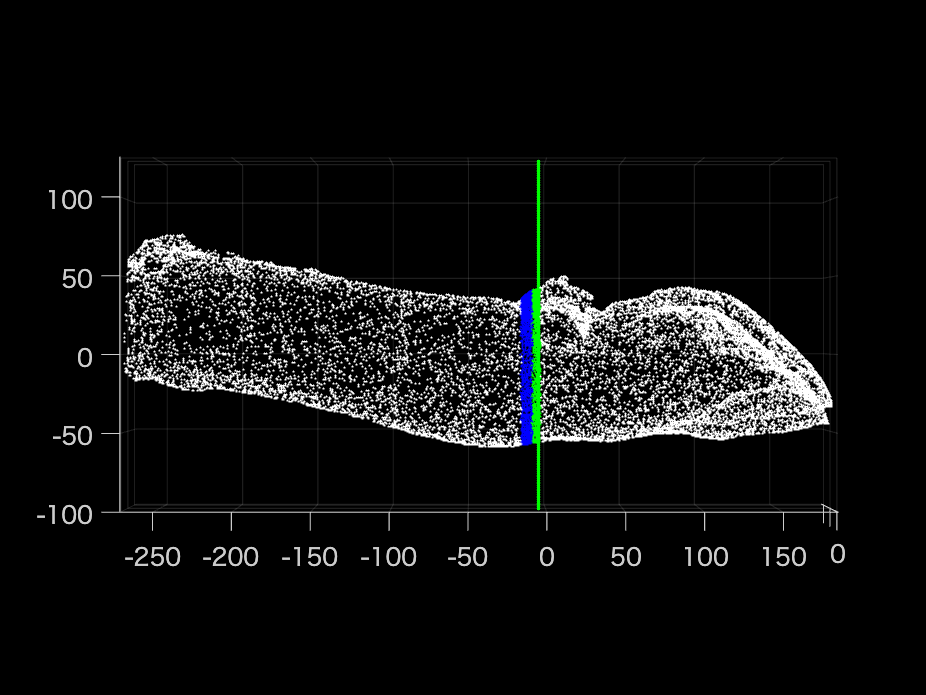

figure;
pcshow(pt, 'w');
hold on;
pcshow(atCir1, 'g');
pcshow(pc_line, 'g', 'MarkerSize', 25);
pcshow(atCir2, 'b', 'AxesVisibility', 'on');
view([0 0])
hold off;


Circum1 = mean(leng1)

Circum1 =      3.102673099554448e+02


Circum2 = mean(leng2)

Circum2 =      3.045652577575578e+02


% hl1 = predictHoofBackWall(Circum1);
% hl2 = predictHoofBackWall(Circum2);
% saveMat = [string(file), Circum1, Circum2, hl1, hl2];
% savename = 'newMethod';
% ext = '.xlsx';
% savexlsx = append(savename, ext);
% writematrix(saveMat, savexlsx, 'WriteMode','append');

% path = 'Third3dfile/'; % macは/windowsは\
% path2 = 'ThirdnumData/';
% chfile = convertStringsToChars(file);
% idx_f = length(chfile);
% nfile = chfile(1:idx_f-4);
% newfile = [path, nfile, '.mat']
% newfile2 = [path2, nfile, '_data_', '.mat'];
% nPoint = ptCloud;
% renPoint = ptCloudA;
% Circum1Pt = pointCloud(atCir1);
% Circum2Pt = pointCloud(atCir2);
% numData = [Circum1, Circum2, hl1, hl2]
% save(newfile, 'nPoint', 'renPoint','Circum1Pt','Circum2Pt','-mat');
% save(newfile2, 'Circum1', 'Circum2', 'hl1', 'hl2', '-mat')
% figpath = 'newfig/';
% figfile1 = [figpath, nfile,'_Section', '.fig'];
% savefig(sfig1, figfile1);
% figpath2 = 'modelfig/'
% figfile2 = [figpath2, nfile,'_Section_model', '.fig'];
% savefig(sfig2, figfile2);
% figpath3 = 'markfig/';
% figfile3 = [figpath3, nfile,'_Section_mark_', '.fig'];
% savefig(sfig3, figfile3);